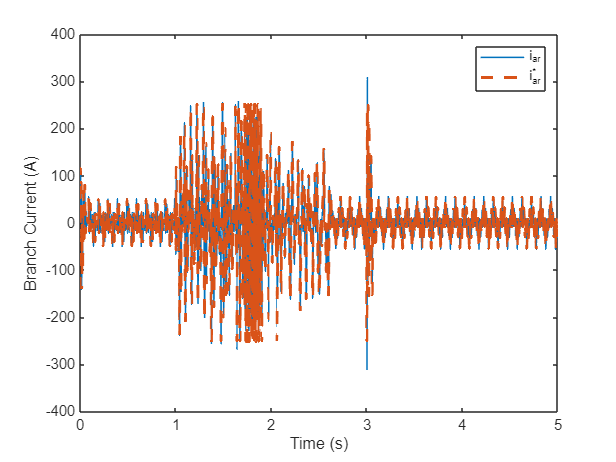

clc
clear all
%% M3C Simulation Script
Ag=7000;			%Grid Amplitude
%Ag=80;
Fg=30;			%Grid Frequency
Am=5000;
%Am=100;
Fm=50;		%Input frequency
Wg=2*pi*Fg;
Wm=2*pi*Fm;
Tf=5; %Simulation time, seconds
Ts=2e-5;	%Sample time
Ns=round(Tf/Ts+1); %includes 0, number of simulation steps
Tsim=linspace(0,Tf,Ns);
Ti=2e-4; %Current Control MPC Sample Time
Tl=1e-4; %Energy Control MPC Superstep
Ni=round(Tf/Ti+1);
Nl=round(Tf/Tl+1);
Np=1;
Tp=Ti*Np;
%A=-[1 0 0 1 0 0 ; 0 1 0 0 1 0 ; 0 0 1 0 0 1 ; -1 -1 -1 0 0 0; 0 0 0 -1 -1 -1]; %M2C incidence matrix
A=-[1 0 0 1 0 0 1 0 0; 0 1 0 0 1 0 0 1 0; 0 0 1 0 0 1 0 0 1; -1 -1 -1 0 0 0 0 0 0; 0 0 0 -1 -1 -1 0 0 0; 0 0 0 0 0 0 -1 -1 -1]; %M3C incidence matrix
m=size(A,2); %number of branches
%N=null(A,'rational');
% N=[-0.4430   -0.4780    0.0994    0.0994
%     0.3611    0.0175   -0.5599    0.0175
%     0.0819    0.4605    0.4605   -0.1169
%     0.6051   -0.0137    0.1976    0.1976
%    -0.4933    0.3094    0.0981    0.3094
%    -0.1118   -0.2957   -0.2957   -0.5070
%    -0.1621    0.4917   -0.2970   -0.2970
%     0.1322   -0.3269    0.4617   -0.3269
%     0.0300   -0.1648   -0.1648    0.6239];
%N=null(A);
N=null(A,'rational');
N1=repmat({N},1,Np);
N1=blkdiag(N1{:});
Vxymax=(Ag+Am); %max possible arm voltage
V0=(1.4815*Vxymax)^2;	%Initial square voltage for each capacitor
V0i=sqrt(V0); %Initial SM Cap Voltage
%V0=150^2;
%V0c = 1*V0;
Vc0=1.5*Vxymax; %SM Cap Voltage Reference
C=20e-3;			%Average SM Capacitance
%C=4.7e-3;
%fs=700;		%Switch frequency
L=200e-4;
%L=2.5e-3;
R=0.001;			%Arm resistance
% Initial States
is0=zeros(m,1); %initial current
vc0=V0i*ones(m,1); %initial cluster cap voltage
Ec0=(C/2/4)*vc0.^2;
% run

Tcur=linspace(0,Tf,Ni);
Ten=linspace(0,Tf,Nl);
Am=Am*ones(1,Ns);
vma=zeros(1,Ns);
vmb=zeros(1,Ns);
vmc=zeros(1,Ns);
vgr=zeros(1,Ns);
vgs=zeros(1,Ns);
vgt=zeros(1,Ns);
is=zeros(m,Ns+1);
vc=zeros(m,Ns+1);
Ec=zeros(m,Ns+1);
vc(:,1:2)=[vc0 vc0];
Ec(:,1:2)=[Ec0 Ec0];
vs=zeros(m,Ns);
vxy=zeros(m,Ns);
%Im=100;
%Ig=-100;
Imdref=10*ones(1,Ns);
Imqref=60*ones(1,Ns);
Igdref=zeros(1,Ns);
Igqref=zeros(1,Ns);
imaref=zeros(1,Ns);
imbref=zeros(1,Ns);
imcref=zeros(1,Ns);
igrref=zeros(1,Ns);
igsref=zeros(1,Ns);
igtref=zeros(1,Ns);
% imaref=Im*cos(Wm*Tsim);
% imbref=Im*cos(Wm*Tsim-2*pi/3);
% imcref=Im*cos(Wm*Tsim+2*pi/3);
% igrref=Ig*cos(Wg*Tsim);
% igsref=Ig*cos(Wg*Tsim-2*pi/3);
% igtref=Ig*cos(Wg*Tsim+2*pi/3);
isref=zeros(m,Ns); %references from l=1 to Np
isxy=zeros(size(A,1),Ns);
iz=zeros(m,Ns);
vcpref=1.49*Vxymax*ones(1,Ns);
vgd=zeros(1,Ns);
vgq=zeros(1,Ns);
vmd=zeros(1,Ns);
vmq=zeros(1,Ns);
gamma_g=zeros(1,Ns);
gamma_m=zeros(1,Ns);
wg=zeros(1,Ns);
wm=zeros(1,Ns);
Tcec=zeros(1,Ns);
vonmax=0.5*Vxymax;
vonmin=-0.5*Vxymax;
von=zeros(1,Ns);
%% Sim
a=0;
u=0;
apll=0;
upll=0;
apm=0;
upm=0;
gm=0;
gg=0;
Tini=1; %initial maneuver time
Tfin=2.6; %final maneuver time
Wmf=10*2*pi; %final maneuver speed
acel=(Wmf-Wm)/(Tfin-Tini); %maneuver acceleration
dVm=Wmf/Wm-1; %maneuver voltage amplitude variation
iAz=false(size([ones(9*Np,1);-ones(9*Np,1)]));
iAv=false(size([ones(Np,1);-ones(Np,1)]));
for t=1:length(Tsim)
    Tini=1; %initial maneuver time
    Tfin=2.6; %final maneuver time
    Wmf=10*2*pi; %final maneuver speed
    if Tsim(t)>Tini
        if Tsim(t)<Tfin
            Wm=Wm+acel*Ts;
            Imdref(t)=200;
            %Am(t)=Am(t)+(dVm/(Tfin-Tini))*(Tsim(t)-Tini)*Am(t);
        end
        %Am(t)=0.2*Am(t);
    end
    vma(t)=Am(t)*cos(gm);
    vmb(t)=Am(t)*cos(gm-2*pi/3);
    vmc(t)=Am(t)*cos(gm+2*pi/3);
    vgr(t)=Ag*cos(gg);
    vgs(t)=Ag*cos(gg-2*pi/3);
    vgt(t)=Ag*cos(gg+2*pi/3);
    gm=gm+Ts*Wm;
    gg=gg+Ts*Wg;
    vxy(:,t)=A'*[vma(t);vmb(t);vmc(t);vgr(t);vgs(t);vgt(t)];

    %isref(:,t)=pinv(A)*[imaref(t);imbref(t);imcref(t);igrref(t);igsref(t);igtref(t)]; %isref in t+1
    isxy(:,t)=A*is(:,t);
    if any(Tcur==Tsim(t)) %control interrupt
        
        %Input Side PLL
        vgdq=(2/3)*[cos(gamma_g(t)) cos(gamma_g(t)-2*pi/3) cos(gamma_g(t)+2*pi/3);-sin(gamma_g(t)) -sin(gamma_g(t)-2*pi/3) -sin(gamma_g(t)+2*pi/3)]*[vgr(t);vgs(t);vgt(t)];
        vgd(t)=vgdq(1);
        vgq(t)=vgdq(2);
        Kp_pll=0.5;
        Ki_pll=1.5;
        ncpll=1-Ti*0.5*Ki_pll/Kp_pll;
        epll=0-vgq(t);
        apll=(ncpll-1)*upll/Kp_pll+apll*ncpll;
        upll=(epll-apll)*Kp_pll;
        wg(t)=-upll+Wg;
        gamma_g(t+1)=gamma_g(t)+Ti*wg(t);
        if gamma_g(t+1)>=2*pi
            gamma_g(t+1)=gamma_g(t+1)-2*pi;
        elseif gamma_g(t+1)<0
            gamma_g(t+1)=gamma_g(t+1)+2*pi;
        end
        
        %Output Side PLL
        vmdq=(2/3)*[cos(gamma_m(t)) cos(gamma_m(t)-2*pi/3) cos(gamma_m(t)+2*pi/3);-sin(gamma_m(t)) -sin(gamma_m(t)-2*pi/3) -sin(gamma_m(t)+2*pi/3)]*[vma(t);vmb(t);vmc(t)];
        vmd(t)=vmdq(1);
        vmq(t)=vmdq(2);
        Kp_pll=0.5;
        Ki_pll=1.5;
        ncpll=1-Ti*0.5*Ki_pll/Kp_pll;
        epll=0-vmq(t);
        apm=(ncpll-1)*upm/Kp_pll+apm*ncpll;
        upm=(epll-apm)*Kp_pll;
        wm(t)=-upm+Wm;
        gamma_m(t+1)=gamma_m(t)+Ti*wm(t);
        if gamma_m(t+1)>=2*pi
            gamma_m(t+1)=gamma_m(t+1)-2*pi;
        elseif gamma_m(t+1)<0
            gamma_m(t+1)=gamma_m(t+1)+2*pi;
        end

        %Total Energy Balance PI control
        imax=200;
        Kpt=6.48156886919677*3;
        Kit=397.264633627808/20;
        nct=1-Ti*0.5*Kit/Kpt;
        e1=(vcpref(t)-sqrt(4*2.*mean(Ec(:,t))./C));
        a=(nct-1)*u/Kpt+a*nct;
        u=(e1-a)*Kpt;
        if u>=imax
             u=imax;
        elseif u<=-imax
             u=-imax;
        end
        Igdref(t)=u;
        igrref(t)=Igdref(t)*cos(gamma_g(t))-Igqref(t)*sin(gamma_g(t));
        igsref(t)=Igdref(t)*cos(gamma_g(t)-2*pi/3)-Igqref(t)*sin(gamma_g(t)-2*pi/3);
        igtref(t)=Igdref(t)*cos(gamma_g(t)+2*pi/3)-Igqref(t)*sin(gamma_g(t)+2*pi/3);
        imaref(t)=Imdref(t)*cos(gamma_m(t))-Imqref(t)*sin(gamma_m(t));
        imbref(t)=Imdref(t)*cos(gamma_m(t)-2*pi/3)-Imqref(t)*sin(gamma_m(t)-2*pi/3);
        imcref(t)=Imdref(t)*cos(gamma_m(t)+2*pi/3)-Imqref(t)*sin(gamma_m(t)+2*pi/3);        
        
        isref(:,t)=pinv(A)*[imaref(t);imbref(t);imcref(t);igrref(t);igsref(t);igtref(t)];
        if any(Ten==Tsim(t))
            %Cluster Energy Control MPC
            tic    
            DV=zeros(9*Np,9*Np);
            DI=zeros(9*Np,Np);
            Dn=zeros(9*Np,9*Np);
            Ilb=-250*ones(9*Np,1);
            Iub=250*ones(9*Np,1);
            Y=zeros(9,Np); 
            izp=zeros(4*Np,1);
    
            %Future Currents and Voltages
            ixab=(2/3)*[1 -1/2 -1/2;0 sqrt(3)/2 -sqrt(3)/2]*[imaref(t);imbref(t);imcref(t)];
            iyab=(2/3)*[1 -1/2 -1/2;0 sqrt(3)/2 -sqrt(3)/2]*[igrref(t);igsref(t);igtref(t)];
            Vxab=(2/3)*[1 -1/2 -1/2;0 sqrt(3)/2 -sqrt(3)/2]*[vma(t);vmb(t);vmc(t)];
            Vyab=(2/3)*[1 -1/2 -1/2;0 sqrt(3)/2 -sqrt(3)/2]*[vgr(t);vgs(t);vgt(t)];
            ixypred=zeros(9,Np);
            tp=linspace(0,Np*Tl,Np);
            iab0xpred=(ixab(1)+j*ixab(2))*exp(j*wm(t)*tp);
            iab0ypred=(iyab(1)+j*iyab(2))*exp(j*wg(t)*tp);
            vab0xpred=(Vxab(1)+j*Vxab(2))*exp(j*wm(t)*tp);
            vab0ypred=(Vyab(1)+j*Vyab(2))*exp(j*wg(t)*tp);        
            T=[1   0 ; -1/2  sqrt(3)/2; -1/2  -sqrt(3)/2]; %Trans Alpha-Beta to abc
            for k=1:Np
                iabcpred=T*[real(iab0xpred(k));imag(iab0xpred(k))];
                irstpred=T*[real(iab0ypred(k));imag(iab0ypred(k))];            
                ixypred(:,k)=pinv(A)*[iabcpred;irstpred];
                vabc=T*[real(vab0xpred(k));imag(vab0xpred(k))];
                vrst=T*[real(vab0ypred(k));imag(vab0ypred(k))];
                vxypred=A'*[vabc;vrst];
                DV((9*k-8):9*Np,(9*k-8):9*k)=repmat(diag(vxypred),Np+1-k,1);
            end
    
    
            lambdao=2*Np;
            lambdav=0.1*Np;
            
            lmax=10;

            %Solver Active Set + Block Coordinate Descent
            for l=1:lmax
                if l==1
                    vonpred=zeros(Np,1);
                end
    
                Y=zeros(6,Np);
                for k=1:Np
                   Dn((9*k-8):9*Np,(9*k-8):9*k)=repmat(vonpred(k)*eye(9),Np+1-k,1);
                end
                Dt=Dn+DV;
                Ecprom=mean(Ec(:,t))*ones(m,1);
                H=2*((Tl)^2*transpose(Dt*N1)*(Dt*N1)+lambdao*(N1')*N1); 
                dz=repmat(Ec(:,t),Np,1)-repmat(Ecprom,Np,1)+Tl*Dt*reshape(ixypred,[9*Np,1]);
                f=2*Tl*transpose(Dt*N1)*dz;
                ub=Iub-reshape(ixypred,[9*Np,1]);
                lb=Ilb-reshape(ixypred,[9*Np,1]);
                iA0z=iAz;
                options = mpcActiveSetOptions;
                options.MaxIterations = 20;
                options.ConstraintTolerance = 1.0e-3;
                [Z1,exitflag,iAz,muz]=mpcActiveSetSolver(H,f,[N1;-N1],[ub;-lb],zeros(0,length(f)),zeros(0,1),iA0z,options);    
                izp=reshape(N1*Z1,[9,Np]);
                %if t>0.35
                %    izp(:,1)=iz;
                %end
            
                for k=1:Np
                    DI((9*k-8):9*Np,k)=repmat(ixypred(:,k)+izp(:,k),Np+1-k,1);
                end
                y=repmat(Ec(:,t),Np,1)+Tl*DV*reshape(ixypred+izp,[9*Np,1])-repmat(Ecprom,Np,1);
                H=2*((Tl)^2*transpose(DI)*DI+lambdav*eye(Np));
                f=2*Tl*transpose(DI)*y;
                %x0 = zeros(Np,1);
                %options = optimoptions('quadprog','Algorithm','active-set');
                %ws = optimwarmstart(x0,options);
                lb=vonmin*ones(Np,1);
                ub=vonmax*ones(Np,1);
                %Z=quadprog(H,f,[],[],[],[],lb,ub,ws);
                options = mpcActiveSetOptions;
                options.MaxIterations = 10;
                options.ConstraintTolerance = 1.0e-3;
                iA0v=iAv;
                [ZX,exitflag,iAv,muv]=mpcActiveSetSolver(H,f,[eye(Np);-eye(Np)],[ub;-lb],zeros(0,length(f)),zeros(0,1),iA0v,options); 
                vonpred=ZX;     
            end     
            Tcec(t)=toc;
            iz(:,t)=izp(:,1);
            von(t)=vonpred(1);
        else
            iz(:,t)=iz(:,t-1);
            von(t)=von(t-1);
            Tcec(t)=Tcec(t-1);
        end
        %Branch Current MPC
        isref(:,t)=isref(:,t)+iz(:,t);
        pl=eye(m);
        lambda=0.00005;
        %lambda=500;
        Ad=expm(-R*Ti*eye(m)/L);
        Bd=(-R*eye(9)/L)\(Ad-eye(m))*(-eye(m)/L);
        g=Ad*is(:,t)-Bd*vxy(:,t)-Bd*von(t)*ones(m,1)-isref(:,t);
        H=2*(Bd'*Bd+lambda*pl);
        f=2*(g'*Bd-lambda*vxy(:,t)')';
        options = mpcActiveSetOptions;
        options.MaxIterations = 100;
        options.ConstraintTolerance = 1.0e-4;
        lb=-vc0+von(t)*ones(m,1);
        %lb(4:6)=zeros(3,1)+von*ones(3,1);
        ub=vc0+von(t)*ones(m,1);
        %ub(1:3)=zeros(3,1)+von*ones(3,1);
        iA0=false(size([ub;-lb]));
        %x = quadprog(H,f,A,b,Aeq,beq,lb,ub,x0,options)
        %mpcActiveSetSolver(H,f,A,b,Aeq,beq,iA0,options)
        [Z,exitflag]=mpcActiveSetSolver(H,f,[eye(9);-eye(9)],[ub;-lb],zeros(0,length(f)),zeros(0,1),iA0,options);
        vs(:,t)=Z-von(t)*ones(m,1);
    else %holding control signals until next interrupt
        iz(:,t)=iz(:,t-1);
        isref(:,t)=isref(:,t-1);
        vs(:,t)=vs(:,t-1);
        vgd(t)=vgd(t-1);
        vgq(t)=vgq(t-1);
        wg(t)=wg(t-1);
        vmd(t)=vmd(t-1);
        vmq(t)=vmq(t-1);
        wm(t)=wm(t-1);
        gamma_g(t+1)=gamma_g(t);
        gamma_m(t+1)=gamma_m(t);
        Igdref(t)=Igdref(t-1);
        Igqref(t)=Igqref(t-1);
        Imdref(t)=Imdref(t-1);
        Imqref(t)=Imqref(t-1);
        igrref(t)=igrref(t-1);
        igsref(t)=igsref(t-1);
        igtref(t)=igtref(t-1);
        imaref(t)=imaref(t-1);
        imbref(t)=imbref(t-1);
        imcref(t)=imcref(t-1); 
        Tcec(t)=Tcec(t-1);
        von(t)=von(t-1);
    end
    is(:,t+1)=is(:,t)+(Ts/L)*(vxy(:,t)-von(t)*ones(m,1))-(Ts/L)*vs(:,t); %discrete model update   
    if t~=1
        Ec(:,t+1)=Ec(:,t)+Ts*diag(vxy(:,t)+von(t)*ones(m,1)-(L/Ts)*(is(:,t)-is(:,t-1))-R*is(:,t))*is(:,t); %discrete energy model update
    end
    if Tsim(t)==3
        Ec(1,t+1)=Ec(1,t+1)+25000;
        Ec(2,t+1)=Ec(2,t+1)-25000;
        Ec(6,t+1)=Ec(6,t+1)+25000;
        Ec(8,t+1)=Ec(8,t+1)-25000;
    end
    vc(:,t+1)=sqrt(2*4.*Ec(:,t+1)./C);
end
vcmean=mean(vc(:,1:end-1));
%%
figure
plot(Tsim,is(1,1:end-1),'LineWidth',1)
hold on
plot(Tsim,[0 isref(1,1:end-1)],'--','LineWidth',2)
legend('i_{ar}','i^{*}_{ar}')
xlabel('Time (s)')
ylabel('Branch Current (A)')

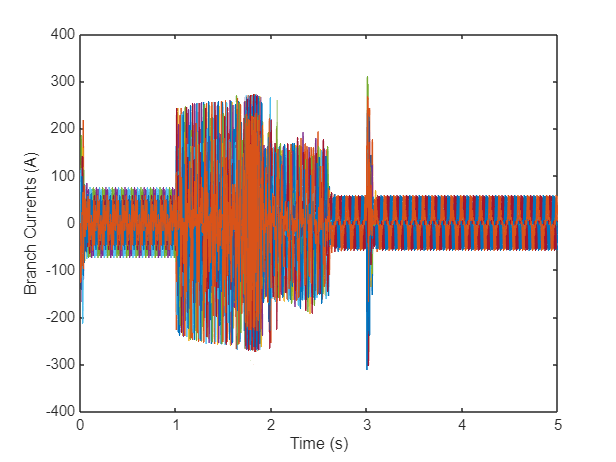

%%
figure
plot(Tsim,is(1,1:end-1),'LineWidth',1)
hold on
plot(Tsim,is(2,1:end-1),'LineWidth',1)
plot(Tsim,is(3,1:end-1),'LineWidth',1)
plot(Tsim,is(4,1:end-1),'LineWidth',1)
plot(Tsim,is(5,1:end-1),'LineWidth',1)
plot(Tsim,is(6,1:end-1),'LineWidth',1)
plot(Tsim,is(7,1:end-1),'LineWidth',1)
plot(Tsim,is(8,1:end-1),'LineWidth',1)
plot(Tsim,is(9,1:end-1),'LineWidth',1)
xlabel('Time (s)')
ylabel('Branch Currents (A)')

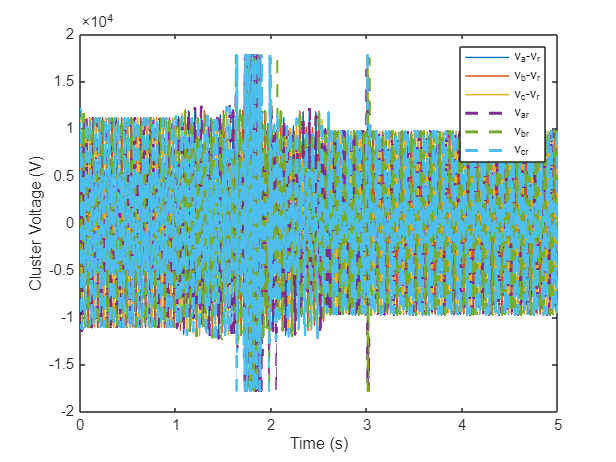

%%
figure
plot(Tsim,vxy(1,:),'LineWidth',1)
hold on
plot(Tsim,vxy(2,:),'LineWidth',1)
plot(Tsim,vxy(3,:),'LineWidth',1)
plot(Tsim,vs(1,:),'--','LineWidth',2)
plot(Tsim,vs(2,:),'--','LineWidth',2)
plot(Tsim,vs(3,:),'--','LineWidth',2)
legend('v_{a}-v_{r}','v_{b}-v_{r}','v_{c}-v_{r}','v_{ar}','v_{br}','v_{cr}')
xlabel('Time (s)')
ylabel('Cluster Voltage (V)')

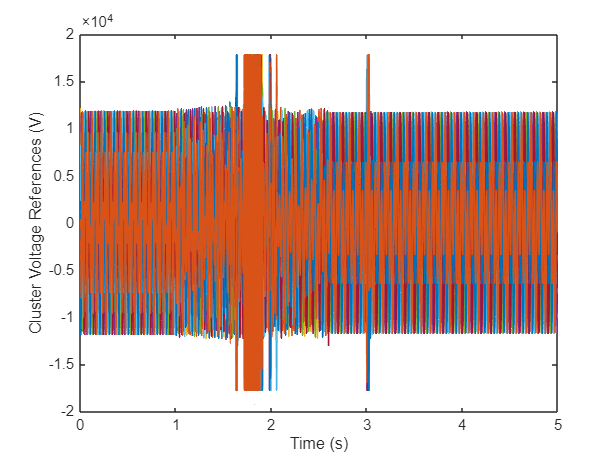

%%
figure
plot(Tsim,vs(1,:),'LineWidth',1.1)
hold on
plot(Tsim,vs(2,:),'LineWidth',1.1)
plot(Tsim,vs(3,:),'LineWidth',1.1)
plot(Tsim,vs(4,:),'LineWidth',1.1)
plot(Tsim,vs(5,:),'LineWidth',1.1)
plot(Tsim,vs(6,:),'LineWidth',1.1)
plot(Tsim,vs(7,:),'LineWidth',1.1)
plot(Tsim,vs(8,:),'LineWidth',1.1)
plot(Tsim,vs(9,:),'LineWidth',1.1)
xlabel('Time (s)')
ylabel('Cluster Voltage References (V)')

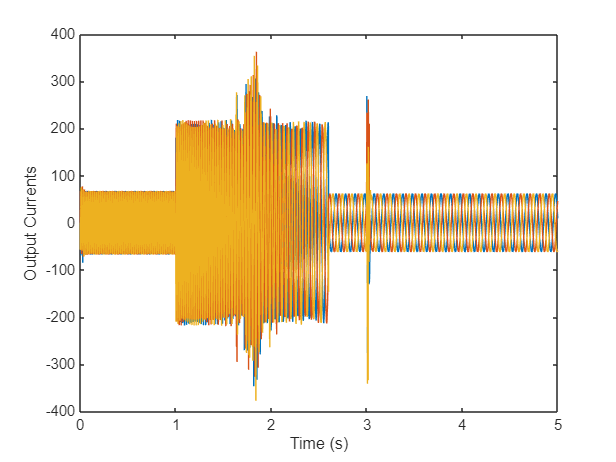

%%
figure
plot(Tsim,isxy(1,:))
hold on
plot(Tsim,isxy(2,:))
plot(Tsim,isxy(3,:))
xlabel('Time (s)')
ylabel('Output Currents')

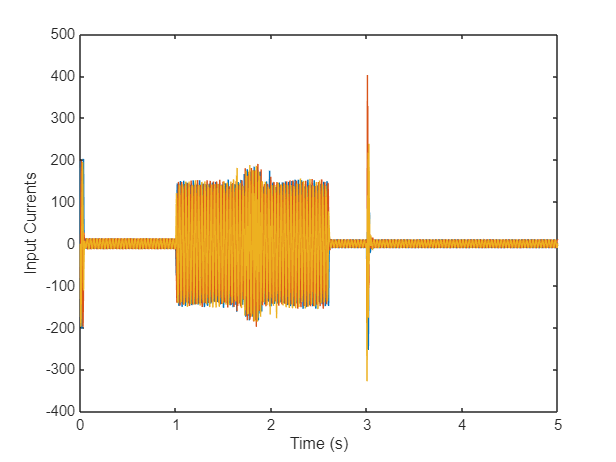

figure
plot(Tsim,isxy(4,:))
hold on
plot(Tsim,isxy(5,:))
plot(Tsim,isxy(6,:))
xlabel('Time (s)')
ylabel('Input Currents')

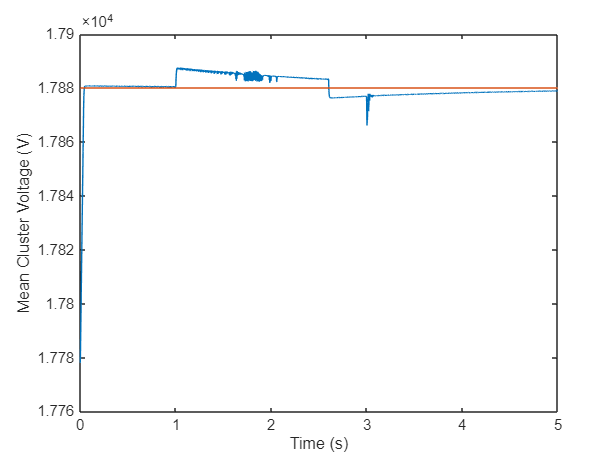

%%
figure
plot(Tsim,vcmean)
hold on
plot(Tsim, vcpref)
xlabel('Time (s)')
ylabel('Mean Cluster Voltage (V)')

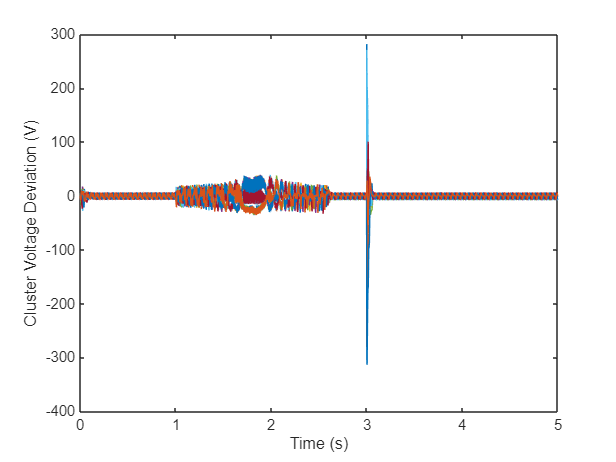

%%
figure
plot(Tsim,vc(1,1:end-1)-vcmean)
hold on
plot(Tsim,vc(2,1:end-1)-vcmean)
plot(Tsim,vc(3,1:end-1)-vcmean)
plot(Tsim,vc(4,1:end-1)-vcmean)
plot(Tsim,vc(5,1:end-1)-vcmean)
plot(Tsim,vc(6,1:end-1)-vcmean)
plot(Tsim,vc(7,1:end-1)-vcmean)
plot(Tsim,vc(8,1:end-1)-vcmean)
plot(Tsim,vc(9,1:end-1)-vcmean)
xlabel('Time (s)')
ylabel('Cluster Voltage Deviation (V)')

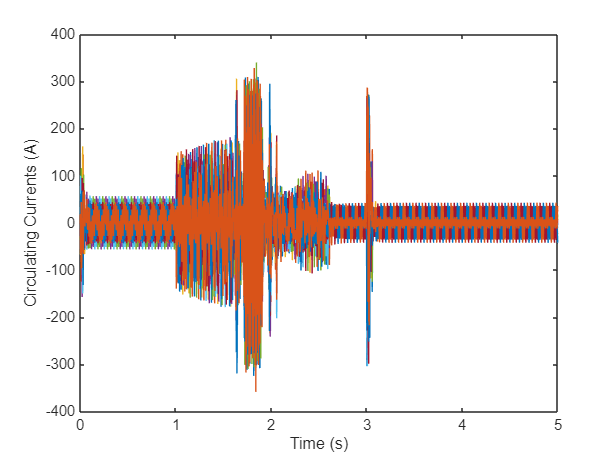

%%
figure
plot(Tsim,iz(1,:))
hold on
plot(Tsim,iz(2,:))
plot(Tsim,iz(3,:))
plot(Tsim,iz(4,:))
plot(Tsim,iz(5,:))
plot(Tsim,iz(6,:))
plot(Tsim,iz(7,:))
plot(Tsim,iz(8,:))
plot(Tsim,iz(9,:))
xlabel('Time (s)')
ylabel('Circulating Currents (A)')

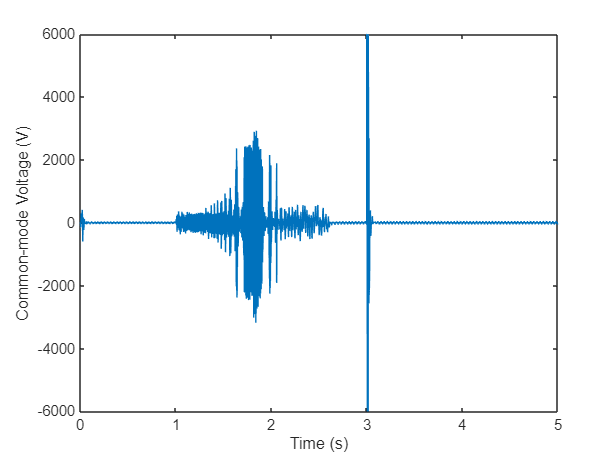

%%
figure
plot(Tsim,von)
xlabel('Time (s)')
ylabel('Common-mode Voltage (V)')

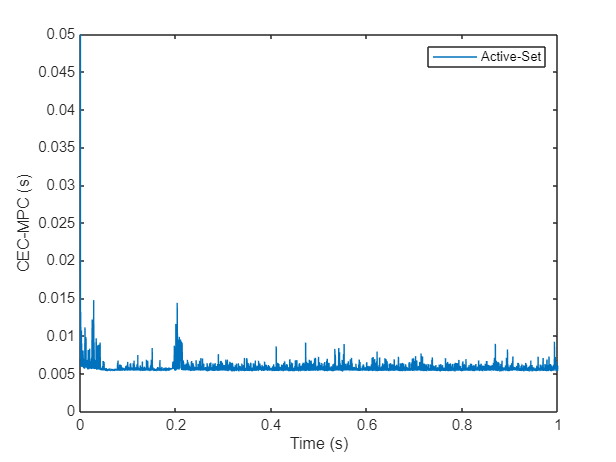

%%
figure
plot(Tsim,Tcec)
xlabel('Time (s)')
ylabel('CEC-MPC (s)')
legend('Active-Set')
xlim([0 1])
ylim([0 0.05])

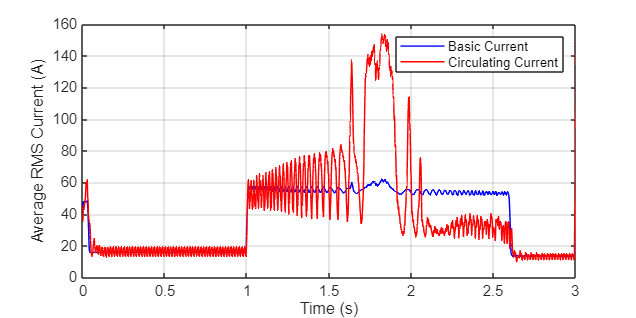

%% irms
iB=pinv(A)*isxy;
b=500; %window
izrms=(sqrt(movmean(iz(1,:).^ 2, b))+sqrt(movmean(iz(2,:).^ 2, b))+sqrt(movmean(iz(3,:).^ 2, b))+sqrt(movmean(iz(4,:).^ 2, b))+sqrt(movmean(iz(5,:).^ 2, b))+sqrt(movmean(iz(6,:).^ 2, b))+sqrt(movmean(iz(7,:).^ 2, b))+sqrt(movmean(iz(8,:).^ 2, b))+sqrt(movmean(iz(9,:).^ 2, b)))/9;
iBrms=(sqrt(movmean(iB(1,:).^ 2, b))+sqrt(movmean(iB(2,:).^ 2, b))+sqrt(movmean(iB(3,:).^ 2, b))+sqrt(movmean(iB(4,:).^ 2, b))+sqrt(movmean(iB(5,:).^ 2, b))+sqrt(movmean(iB(6,:).^ 2, b))+sqrt(movmean(iB(7,:).^ 2, b))+sqrt(movmean(iB(8,:).^ 2, b))+sqrt(movmean(iB(9,:).^ 2, b)))/9;
figure
plot(Tsim,iBrms,'b', 'linewidth', 1)
hold on
plot(Tsim,izrms,'r', 'linewidth', 1)
set(gcf,'Position',[300 300 1000 500])
grid on
xlim([0 3])
xlabel('Time (s)')
ylabel('Average RMS Current (A)')
%ylim([0 30])
legend('Basic Current','Circulating Current')

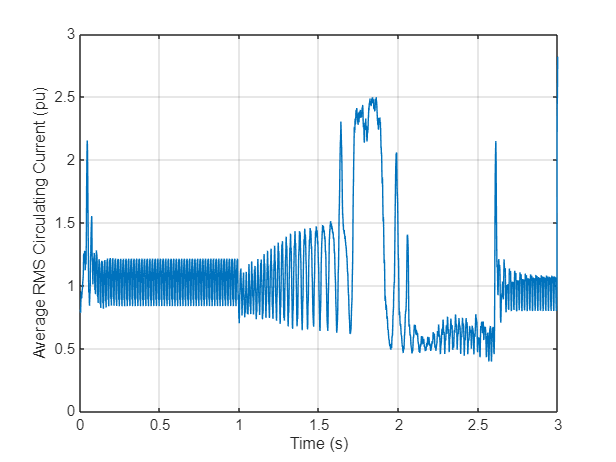

%%
figure
plot(Tsim,izrms./iBrms)
xlim([0 3])
grid on
xlabel('Time (s)')
ylabel('Average RMS Circulating Current (pu)')

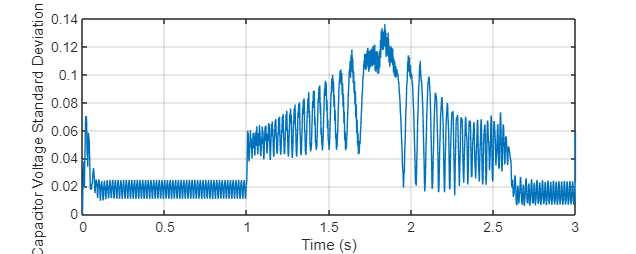

%% VSD
%vcprom=(vcar+vcas+vcbr+vcbs+vccr+vccs)./6;
vsd=sqrt(((100.*(vc(1,1:end-1)-vcmean)./vcmean).^2+(100.*(vc(2,1:end-1)-vcmean)./vcmean).^2+(100.*(vc(3,1:end-1)-vcmean)./vcmean).^2+(100.*(vc(4,1:end-1)-vcmean)./vcmean).^2+(100.*(vc(5,1:end-1)-vcmean)./vcmean).^2+(100.*(vc(6,1:end-1)-vcmean)./vcmean).^2+(100.*(vc(7,1:end-1)-vcmean)./vcmean).^2+(100.*(vc(8,1:end-1)-vcmean)./vcmean).^2+(100.*(vc(9,1:end-1)-vcmean)./vcmean).^2)/9);
figure
plot(Tsim,vsd)
set(gcf,'Position',[300 300 1000 400])
xlim([0 3])
%ylim([0 550])
grid on
xlabel('Time (s)')
ylabel('Capacitor Voltage Standard Deviation (%)')